Maximum channel capacity after applying Shannon's Law at existing conditions is 3829


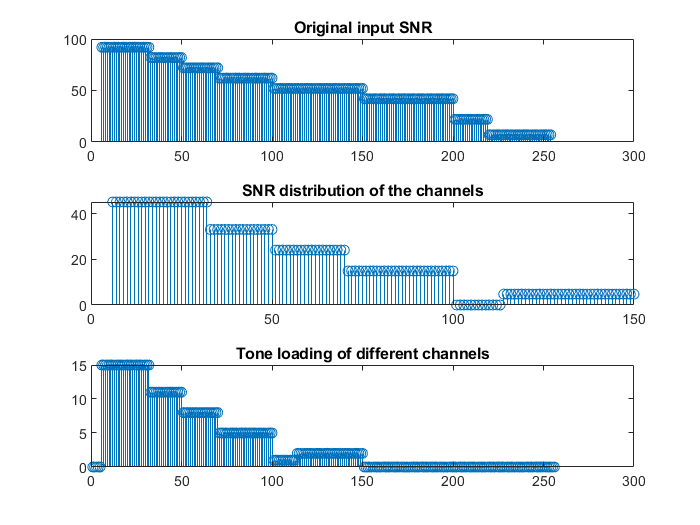

t=1:256; % Tone loading table not yet used.
snr=SPN_to_SNR_converter(); % Get the SNR table
b=adaptive_fine_gains(snr,1000); % Get the adaptive bit loading

b=[b.nbits_rounded]; % Get only the number of rounded bits in the channel
%t = [7 14 21 4 11 18 1 8 15 22 5 12 19 2 9 16 23 6 13 20 3 10 17]; % Tone ordering table
%b = [0 1 2 4 2 3 2 5 0 2 0 2 7 1 6 3 8 2 9 0 2 12 2] % Bits in each channel
[~,Nsc] = size(b); % Number of sub-carriers
data = creverb1(Nsc); % PRBS
QAM_symbols = qam_mod(data,b,t) % QAM symbols

QAM_symbols = 	1.0e+02 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.4100 - 0.1300i
  -0.2900 - 1.7900i
  -0.7100 - 0.3500i
   0.8300 - 0.4700i
  -0.6500 + 0.0900i


bit_stream_rcvd = qam_demod(QAM_symbols,b); % Perform demod on the receiver end
data = data(1:sum(b)); % Get the BER
err = sum(bit_stream_rcvd ~= data)

err = 0